# OFDM Development Environment

Students: Max Neumann, Michael Hammerl

This simulation implements a complete DRM (Digital Radio Mondiale) system with OFDM modulation for image transmission over various channels

start_up;

                            OFDM-Workshop                              
* Adding DRM to MATLAB directory search path ...


SwitchDemoSync = true; % Flag to enable additional visualization plots

## Transmission Parameters Initialization

The satellite link model uses the following parameters: 

### Antenna Gain

- Uplink Antenna Gain: $$G_{ground,u} = 10\log_{10}\left(\eta \left(\frac{\pi D}{\lambda_u}\right)^2\right)$$ [dBi]

- Downlink Antenna Gain: $$G_{ground,d} = 10\log_{10}\left(\eta \left(\frac{\pi D}{\lambda_d}\right)^2\right)$$ [dBi]

### Free Space Path Loss

- Uplink FSPL: $$FSPL_u = 20\log_{10}\left(\frac{4\pi R}{\lambda_u}\right)$$ [dB]

- Downlink FSPL: $$FSPL_d = 20\log_{10}\left(\frac{4\pi R}{\lambda_d}\right)$$ [dB]

### Rain Attenuation (simplified ITU-R P.618 model)

- Geometric rain path length: $$L_r = \frac{h_r}{\sin(El)}$$ [m]

- Specific attenuation: $$\gamma_R = k_r \cdot R_{rain}^{\alpha_r}$
$ [dB/km]

- Effective rain path length: $$L_{eff} = L_r \cdot r_f$ [km] (where $r_f$ is reduction factor)$

- Rain attenuation: $$A_{rain} = \gamma_R \cdot L_{eff}$$ [dB]

### Link Budget Calculations

- Cable loss: $$L_{cable} = l_{cable} \cdot l_{\textit{per meter}}$$ [dB]

- EIRP of base station: $$EIRP_{ground} = P_{tx} + G_{tx} - L_{cable} + G_{ground,u}$$ [dBm]

- Received power at satellite: $$P_{sat,rx} = EIRP_{ground} + G_{sat,rx} - FSPL_u - A_{rain} - L_{sat,rx}$$ [dBm]

- Satellite output power: $$P_{sat,tx} = P_{sat,rx} + G_{amp} - L_{sat,tx}$$ [dBm]

- EIRP of satellite: $$EIRP_{sat} = P_{sat,tx} + G_{sat,tx}$$ [dBm]

- Received power at ground station: $$P_{rx,ground} = EIRP_{sat} + G_{ground,d} - L_{cable} - FSPL_d - A_{rain}$$ [dBm]

### Noise and SNR

- Noise power: $$N_{dBm} = 10\log_{10}(k \cdot T \cdot B) + 30$ [dBm] (where $k = 1.38 \times 10^{-23}$ J/K)$

- SNR: $$SNR_{dB} = P_{rx,ground} - N_{dBm}$$ [dB]

tx_power = 7 + 30; % 7 dBm output power of Adalm Pluto + 30 dBm amplifier (assumption)
link = SatelliteLink('tx_center_frequency', 2400.113 * 1e6, 'tx_gain', 0, 'rx_gain', 40, 'tx_power', tx_power);
link.displayLinkBudget();

Link Budget Results
  Base Station TX Center Frequency: 2400113000.00 Hz
  Calculated RX (Downlink) Center Frequency: 739613000.00 Hz
  Baseband Sample Rate: 2700.00 Hz
  TX Gain: 0.00 dB
  RX Gain: 40.00 dB
  Antenna Gain (Uplink): 27.37 dBi
  Antenna Gain (Downlink): 17.15 dBi
  Cable Loss: 1.20 dB
  FSPL Uplink: 191.12 dB
  FSPL Downlink: 180.90 dB
  Rain Attenuation: 3.68 dB
  EIRP Base Station (Uplink): 63.17 dBm
  Power Received at Satellite (Uplink): -103.63 dBm
  EIRP Satellite (Downlink): -45.63 dBm
  Power Received at Base Station (Downlink): -214.27 dBm
  Receiver Noise Power: -113.98 dBm
  SNR: -100.29 dB (9.35e-11 linear)


## DRM Initialization

DRM standard defines robustness modes (A-D) and spectrum occupancy (0-5) 

- Mode D 

- Occupancy 3

stDRM.mode = 4;      % Corresponds to Mode D
stDRM.occupancy = 3;

check_drm_bandwidth(link.baseStation.baseband_sample_rate, stDRM.mode, stDRM.occupancy);

DRM Bandwidth for 2.7kHz constraint:
  Mode: 4
  Occupancy: 3
  FFT Size: 112
  Carriers: 89
  Spacing: 24.11 Hz
  Bandwidth: 2.15 kHz ✓


## OFDM Initialization

OFDM parameters based on DRM standard: 

- $N_{FFT}$: FFT size for the mode/occupancy 

- $N_g$: Guard interval length (cyclic prefix) 

- $N_s = N_{FFT} + N_g$: Total symbol length

stOFDM.iNfft = get_drm_n_useful(stDRM.mode,stDRM.occupancy);
stOFDM.iNg = get_drm_n_guard(stDRM.mode,stDRM.occupancy);
stOFDM.iNs = stOFDM.iNfft + stOFDM.iNg;

## Generate DRM Frame

Encodes image data into DRM frames with call sign Each frame contains multiple OFDM symbols with data and pilots

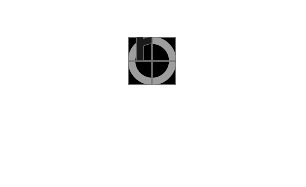

image_path = 'th-rosenheim-logo-colored-square.png';
greyscale = true;
call_sign = 'DL0FHR';
[Slk, M, image_size, iNofFramesNeeded, iNOfFrames] = generate_drm_frames(stDRM, stOFDM, image_path, greyscale, call_sign);

figure(362)
image = imread(image_path);
if greyscale
    image = rgb2gray(image);
end
imshow(uint8(image));

## OFDM Modulator

OFDM modulation process: 

1. IFFT: $s(n) = \frac{1}{N}\sum_{k=0}^{N-1} S(k) e^{j2\pi kn/N}$ 

2. Add cyclic prefix: copy last $N_g$ samples to beginning 

3. Parallel to serial conversion

SlkTemp = ifft(fftshift(Slk,2),stOFDM.iNfft,2);

% Add Cyclic Prefix: copy last Ng samples to beginning
% CP prevents ICI and helps with synchronization: $s_{CP}(n) = s(n-N_g)$ for $n=0,1,...,N_g-1$
SlkTemp = [SlkTemp(:,end-stOFDM.iNg+1:end) SlkTemp];

% Parallel to Serial Conversion: reshape to 1-D signal
SlkTemp = SlkTemp.';
vfcTransmitSignal = SlkTemp(:);

## Channel

Different channel options: 

0: Ideal (no distortion) 

1: General Simulation

2: Simulated QO-100 satellite channel 

3: Adalm Pluto SDR (Satellite) 

4: Adalm Pluto SDR (USB)

iSwitchChannel = 1;

switch iSwitchChannel
    case 0 % ideal channel
        % Repeat iG Frames
        iG = 2;
        vfcTransmitSignal = repmat(vfcTransmitSignal,iG,1);

        fprintf('Using ideal channel...\n');
        vfcReceiveSignal = vfcTransmitSignal;

    case 1 % simulated channel
        fprintf('Using simulated channel...\n');

        % Repeat iG Frames
        iG = 2;
        vfcTransmitSignal = repmat(vfcTransmitSignal,iG,1);

        stChannel = initChannel();
        vfcReceiveSignal = channel_sim(vfcTransmitSignal,stChannel);

    case 2 % Simulate Satellite Communication for Q0-100
        % Repeat iG Frames
        iG = 2;
        vfcTransmitSignal = repmat(vfcTransmitSignal,iG,1);

        % Update to use the link object instead of stSat
        vfcReceiveSignal = simulate_qo100_channel(vfcTransmitSignal, link);

    case 3 % Use Adalm Pluto (Satellite)
        link.useSameFrequency = false;
        % SDR come from the link object
        vfcReceiveSignal = LoopbackAdalmPlutoSat(vfcTransmitSignal, link);

        % Frequency offset compensation
        freqShift = 282; % Measured frequency offset in Hz

        % Convert to angular frequency
        delta_Omega = 2*pi*(freqShift/link.baseStation.baseband_sample_rate);
        vPhaser = exp(-1i * delta_Omega * [0:length(vfcReceiveSignal)-1])';

        vfcReceiveSignal = vfcReceiveSignal .* vPhaser;

        % Display spectrum with pilot markers
        figure(375);
        pwelch(vfcReceiveSignal, [],[],[], link.baseStation.baseband_sample_rate);
        hold on;
        xline(link.baseStation.baseband_sample_rate*0.750/12000);
        xline(link.baseStation.baseband_sample_rate*2.250/12000);
        xline(link.baseStation.baseband_sample_rate*3.000/12000);
        xticks([ ...
            link.baseStation.baseband_sample_rate*0.750/12000,...
            link.baseStation.baseband_sample_rate*2.250/12000,...
            link.baseStation.baseband_sample_rate*3.000/12000
            ])

    case 4 % Use Adalm Pluto (USB) loopback
        link.useSameFrequency = true;
        % SDR come from the link object
        vfcReceiveSignal = LoopbackAdalmPluto(vfcTransmitSignal, link);
end

Using simulated channel...


## Detect Robustness Mode

Detection algorithm uses autocorrelation between received signal and each possible mode $R_{xx}(\Delta k) = \sum_{n=0}^{N-1} x(n) \cdot x^*(n-\Delta k)$ The mode with highest correlation peak is selected

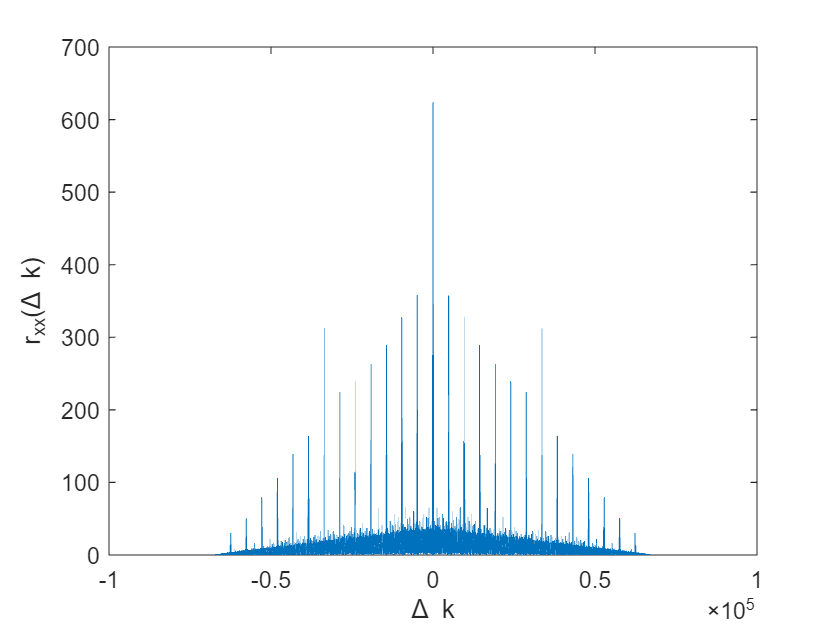

Robustness Mode: D


[iModeEst, iNfft, iNg, iNs, iNOfSymbolsPerFrame] = detect_robustness_mode(vfcReceiveSignal, stDRM.occupancy, SwitchDemoSync);

## Synchronization

OFDM synchronization uses cyclic prefix correlation: $R(k) = \sum_{n=0}^{N_g-1} x^*(n+k) \cdot x(n+k+N_{FFT})$ 

- Time sync: $\hat{k} = \arg\max_k |R(k)|$ 

- Frequency offset: $\Delta\hat{f} = \frac{\angle R(\hat{k})}{2\pi T_{useful}}$

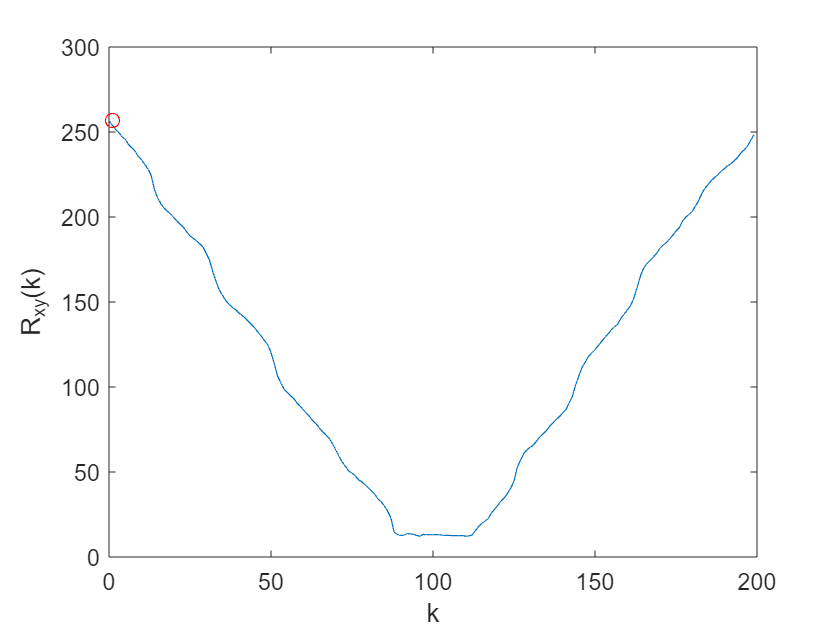

vfcReceiveSignal = sync(vfcReceiveSignal, iNs, iNg, iNfft, SwitchDemoSync);

## OFDM Demodulator

Reverses the modulation process: 

1. Serial to parallel conversion 

2. Remove cyclic prefix 3. FFT: $R(k) = \sum_{n=0}^{N-1} r(n) e^{-j2\pi kn/N}$

RlkTemp = reshape(vfcReceiveSignal,iNs,[]).';

% Remove Cyclic Prefix
RlkTemp = RlkTemp(:,stOFDM.iNg+1:end);

% FFT
Rlk = fftshift(fft(RlkTemp,stOFDM.iNfft,2),2);

## Frame Detection

Uses cross-correlation with known pilot pattern: $M(l,k) = \sum_{l'=0}^{L-1}\sum_{k'=0}^{K-1} R(l+l',k+k') \cdot P^*(l',k')$ 

Frame start indices detected from correlation peaks

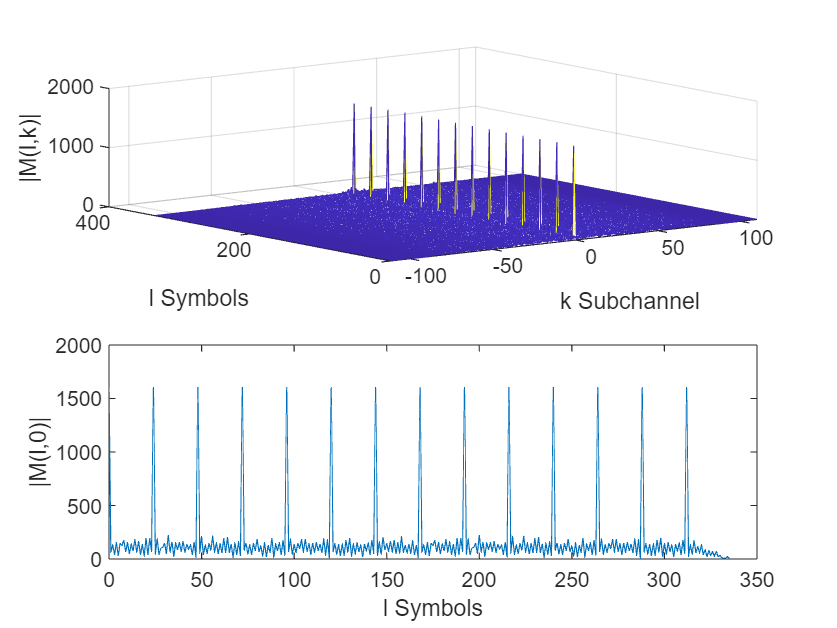

Plk = get_drm_pilot_frame(iModeEst,stDRM.occupancy);
Mlk = xcorr2(Rlk,Plk);
Mlk(1:iNOfSymbolsPerFrame-1,:) = [];

if SwitchDemoSync
    figure(201);
    subplot(2,1,1)
    mesh([0:2*iNfft-2]-iNfft,0:size(Mlk,1)-1,abs(Mlk))

    xlabel('k Subchannel')
    ylabel('l Symbols')
    zlabel('|M(l,k)|')

    subplot(2,1,2)
    plot(0:size(Mlk,1)-1,abs(Mlk(:,iNfft)))
    xlabel('l Symbols')
    ylabel('|M(l,0)|')
end


iNOfFrames = floor(size(Mlk,1)/iNOfSymbolsPerFrame);

[~ , viFrameStart] = maxk(abs(Mlk(:,iNfft)),iNOfFrames);

viFrameStart = sort(viFrameStart);
viFrameStart(end)=[];

viFrameSymbols = 0:iNOfSymbolsPerFrame-1;

for iFrame = 1:length(viFrameStart)
    stRlk{iFrame} = Rlk(viFrameStart(iFrame)+viFrameSymbols,:);
end

% Run first Frame
Rlk = vertcat(stRlk{1:iNofFramesNeeded});
iNOfSymbolsTotal = iNofFramesNeeded * iNOfSymbolsPerFrame;

## Fine Synchronization

Corrects residual phase errors using pilot tones For each symbol l: 

1. Calculate phase difference: $\phi(l,k) = \angle(R(l,k) \cdot P^*(l,k))$ 

2. Linear regression: $\phi(l,k) \approx ak + b$ 

3. Correction: $R_{corr}(l,k) = R(l,k) \cdot e^{-j(ak+b)}$

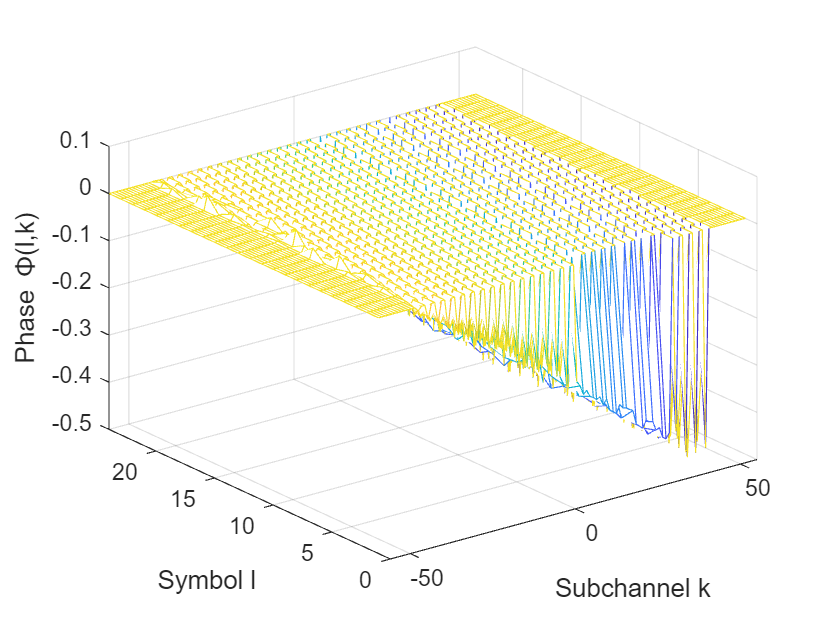

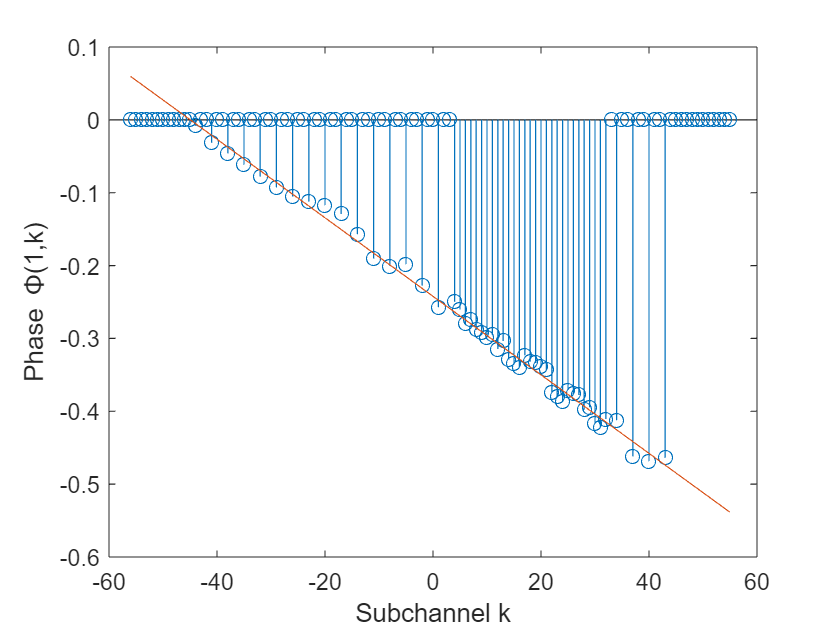

Plk = get_drm_pilot_frame(iModeEst,stDRM.occupancy);

% Apply fine synchronization per frame
for iFrame = 1:iNofFramesNeeded
    icurFrameStart = (iFrame-1)*iNOfSymbolsPerFrame+1;
    icurFrameEnd = iFrame*iNOfSymbolsPerFrame;
    Rlk(icurFrameStart:icurFrameEnd,:) = fine_sync(Rlk(icurFrameStart:icurFrameEnd,:), Plk, iNfft, SwitchDemoSync);
end

## Channel Estimation and Equalization

Channel estimation at pilot positions: $H(k_p) = \frac{R(k_p)}{P(k_p)}$ 

Interpolation methods: 

- Spline: Cubic spline interpolation between pilots 

- Wiener: MMSE estimation based on channel statistics  $\hat{H}(k) = \mathbf{w}^H \mathbf{H_p}$ where $\mathbf{w} = \mathbf{R}^{-1}\mathbf{r}$  $\mathbf{R} = E[\mathbf{H_p}\mathbf{H_p}^H]$, $\mathbf{r} = E[\mathbf{H_p}H^*(k)]$ 

Equalization: $S_{est}(k) = \frac{R(k)}{\hat{H}(k)}$

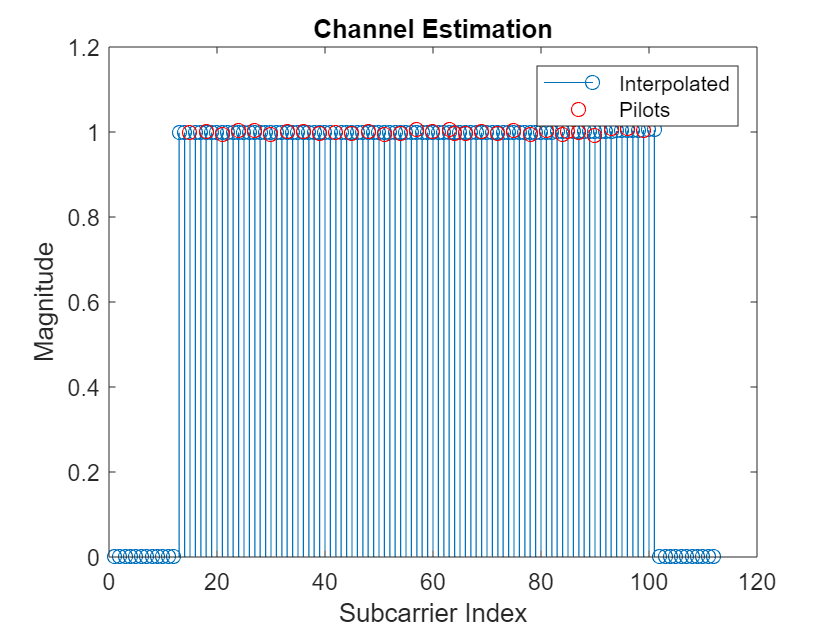

cInterpolater = 'Wiener';  % 'Spline' or 'Wiener'
for iFrame = 1:iNofFramesNeeded
    icurFrameStart = (iFrame-1)*iNOfSymbolsPerFrame+1;
    icurFrameEnd = iFrame*iNOfSymbolsPerFrame;
    Rlk(icurFrameStart:icurFrameEnd,:) = channel_estimation_equalization(Rlk(icurFrameStart:icurFrameEnd,:), Plk, stOFDM.iNfft, stOFDM.iNg, iModeEst, stDRM.occupancy, cInterpolater, SwitchDemoSync);
end

## Reconstruct Image

Demaps received symbols to bits, deinterleaves, and reconstructs the image Image data extraction follows reverse of transmission process

[reconstructed_image, Received_call_sign] = reconstruct_drm_image(Rlk, stDRM, M, image_size, call_sign);

% Display the call sign
fprintf('Received call sign: %s\n', char(Received_call_sign));

Received call sign: DL0FHR


## Graphical Output

Shows comparison between transmitted and received data

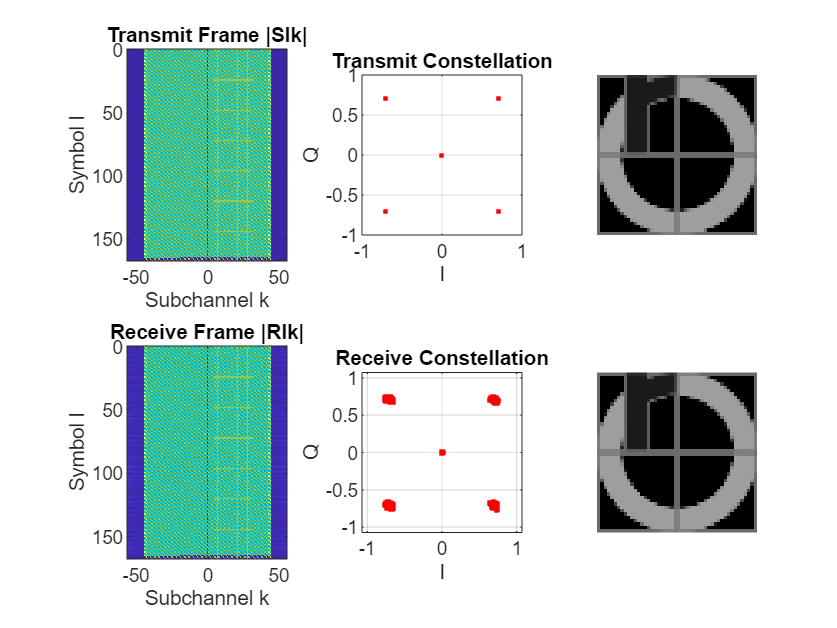

SlkTemp = repmat(get_drm_data_template_frame(stDRM.mode, stDRM.occupancy), iNofFramesNeeded, 1);
figure(1)
subplot(2,3,1)
imagesc((1:stOFDM.iNfft)-get_drm_dc_position(stDRM.mode,stDRM.occupancy),0:size(Slk,1)-1,abs(Slk))
xlabel('Subchannel k')
ylabel('Symbol l')
title('Transmit Frame |Slk|')

subplot(2,3,2)
plot(Slk(SlkTemp ==1),'r.')
grid
fLimit = max(max(abs(Slk(SlkTemp ==1))));
axis square
axis([-fLimit fLimit -fLimit fLimit])
xlabel('I')
ylabel('Q')
title('Transmit Constellation')

subplot(2,3,3)
image = imread(image_path);
if greyscale
    image = rgb2gray(image);
end
imshow(uint8(image));

subplot(2,3,4)
imagesc((1:stOFDM.iNfft)-get_drm_dc_position(stDRM.mode,stDRM.occupancy),0:size(Rlk,1)-1,abs(Rlk))
xlabel('Subchannel k')
ylabel('Symbol l')
title('Receive Frame |Rlk|')

subplot(2,3,5)
plot(Rlk(SlkTemp ==1),'r.')
grid
fLimit = max(max(abs(Rlk(SlkTemp ==1))));
axis square
axis([-fLimit fLimit -fLimit fLimit])
xlabel('I')
ylabel('Q')
title('Receive Constellation')

subplot(2,3,6)
imshow(uint8(reconstructed_image));

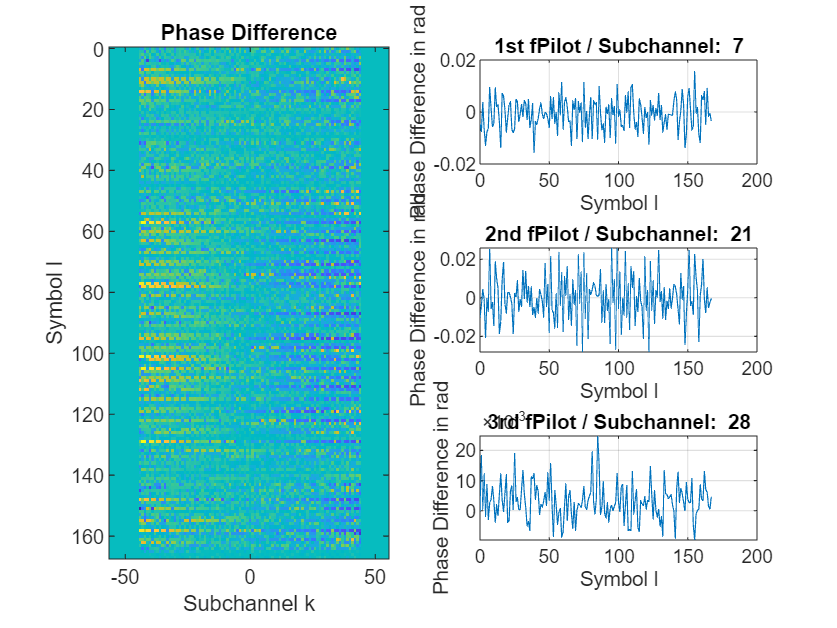



if SwitchDemoSync
    figure(2)
    subplot(3,2,[1 3 5])
    mfcPhase = angle(conj(Slk).*Rlk);
    imagesc((1:stOFDM.iNfft)-get_drm_dc_position(stDRM.mode,stDRM.occupancy),0:iNOfSymbolsTotal-1,mfcPhase)
    xlabel('Subchannel k')
    ylabel('Symbol l')
    title('Phase Difference')

    fpilot_position = get_drm_fpilot_position(stDRM.mode)+get_drm_dc_position(stDRM.mode,stDRM.occupancy);
    dc_position = get_drm_dc_position(stDRM.mode,stDRM.occupancy);
    subplot(3,2,2)
    plot(0:iNOfSymbolsTotal-1,mfcPhase(:,fpilot_position(1)))
    xlabel('Symbol l')
    ylabel('Phase Difference in rad')
    title(['1st fPilot / Subchannel:  ' num2str(fpilot_position(1)-dc_position)])
    grid


    subplot(3,2,4)
    plot(0:iNOfSymbolsTotal-1,mfcPhase(:,fpilot_position(2)))
    xlabel('Symbol l')
    ylabel('Phase Difference in rad')
    title(['2nd fPilot / Subchannel:  ' num2str(fpilot_position(2)-dc_position)])
    grid


    subplot(3,2,6)
    plot(0:iNOfSymbolsTotal-1,mfcPhase(:,fpilot_position(3)))
    xlabel('Symbol l')
    ylabel('Phase Difference in rad')
    title(['3rd fPilot / Subchannel:  ' num2str(fpilot_position(3)-dc_position)])
    grid
end